# **Final Vulcan Plotting**

## **Constants**

## Transfer in

TA_KT = thetastar_trans_f - thetastar_trans_0;
gamma_tat_arr = gamma2;
v_inf_tat_arr = v_inf2;
e_tat_arr = e

e_tat_arr = 4.5954

a_tat_arr = a

a_tat_arr = -1.9664e+03

eta_tat_arr = acos(-1 / e_kuat_arr)

eta_tat_arr = 1.6596

## Transfer out

eta_tat_dep = acos(-1 / e_dept)

eta_tat_dep = 2.8733

gamma_tat_dep = gam_i

gamma_tat_dep = 0.0977

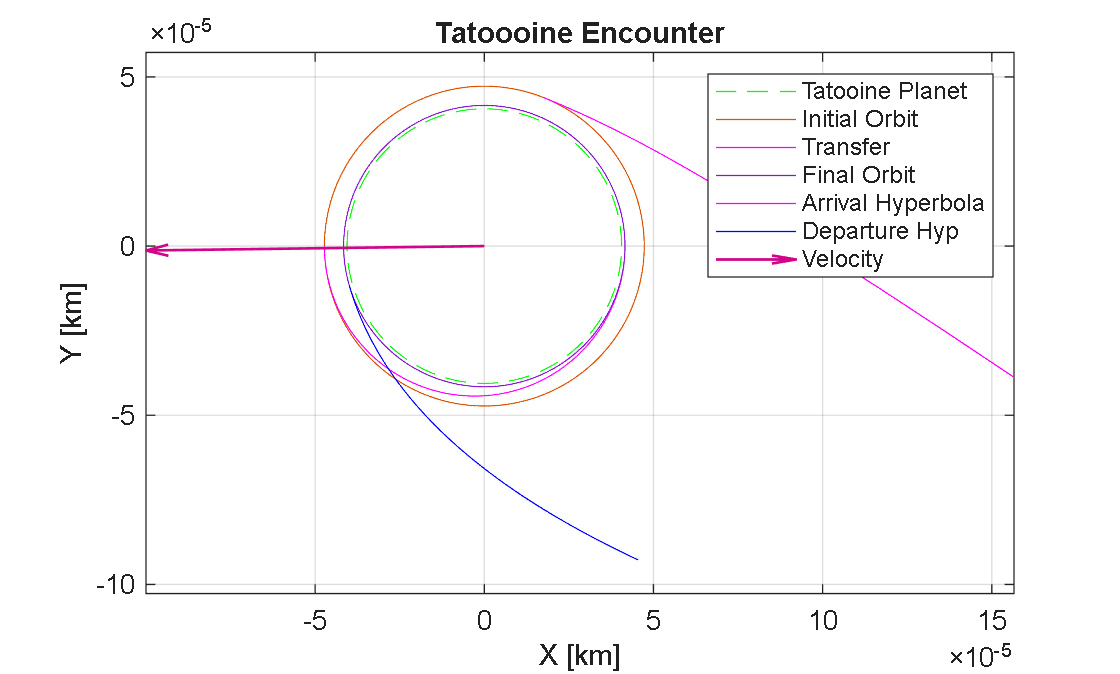

w_vulcan = deg2rad(100);
w_kuat = w_vulcan + TA_VK;
w_tat = w_kuat + TA_KT;
figure

w_offset = deg2rad(-18);

orbitplot2D(r_tatooine, 0, 0:0.001:2*pi, 0, "Tatooine Planet", r_scale = AU, color='g', LineStyle="--"); hold on
orbitplot2D(h_tatooine_initial, 0, 0:0.001:2*pi, w_kuat_geo, "Initial Orbit", r_scale = AU);
orbitplot2D(a_trans_orbit, e_orbit, -pi : 0.001 :0, 0, "Transfer", r_scale = AU, LineStyle = "-", color = "m");
orbitplot2D(h_tatooine_final, 0, 0 : 0.001 : 2 * pi, 0, "Final Orbit", r_scale = AU, LineStyle = "-");

orbitplot2D(a_tat_arr, e_tat_arr, -deg2rad(82):0.001:0, w_tat + eta_tat_arr - deg2rad(gamma_tat_arr) - pi / 2, "Arrival Hyperbola", r_scale = AU, color = "m")
orbitplot2D(a_dept, e_dept, 0:0.001:deg2rad(100), w_tat - pi / 2 - eta_tat_dep, "Departure Hyp", r_scale = AU, color = "b")

planet_velocity = 1e-4 * [-sin(w_tat), cos(w_tat)];
quiver(0, 0, planet_velocity(1), planet_velocity(2), "off", "filled", LineWidth = 1, DisplayName = "Velocity")
xlabel("X [km]")
ylabel("Y [km]")
grid on
axis equal
legend()
title("Tatoooine Encounter")
hold off